# Preprocessing the docuement network data to extract the linkages and the content information

clear all
close all
clc
load('citeseer_raw');

Check the unique paper id set

paper_unique_id = unique(paper_id);
if length(paper_id) == length(paper_unique_id)
    s = sprintf('The paper id is unique and no duplications');
    disp(s)
else
    error('repetitive docuemnts in the content');
end

The paper id is unique and no duplications


check if the linkages' paper id are in the content

% cite_set = unique(cite_id);
% cited_set = unique(cited_id);
% 
% cite_indicator = ismember(cite_set, paper_id);
% cited_indicator = ismember(cited_set, paper_id);
% 
% if all(cite_indicator) & all(cited_indicator)
%     s = sprintf('Test passed for the linkages'' network');
%     disp(s);
% else 
%     error('linkages'' docuement set is not included in the content');
% end

Construct the linkage network matrix C

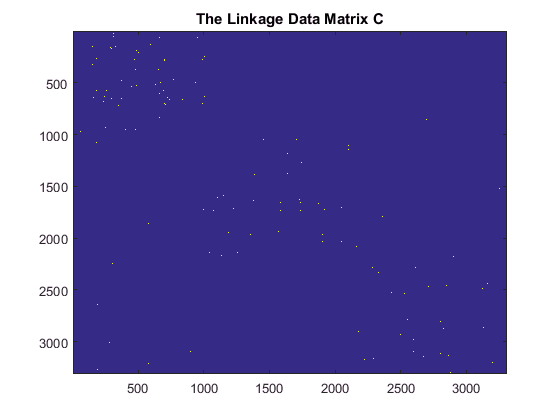

[~, cite_index] = ismember(cite_id, paper_id);
[~, cited_index] = ismember(cited_id, paper_id);
rm_citations = cite_index & cited_index;
rm_idx = find(rm_citations == 0);
cite_index(rm_idx) = [];
cited_index(rm_idx) = [];

C = sparse(cite_index, cited_index, ones(length(cite_index),1), length(paper_id), length(paper_id));
C = C | C.';
imagesc(C);
title('The Linkage Data Matrix C');

The W matrix

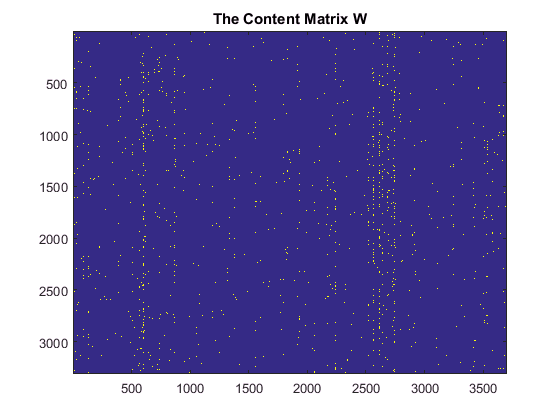

idc = find(sum(W, 1) == 0); % column sum to 0
W(:, idc) = [];

idr = find(sum(W, 2) == 0); % raw sum to 0
W(idr,:) = [];

W = W;
imagesc(W);
title('The Content Matrix W')

Save the dataset

save 'citeseer.mat' 'C' 'W' 'paper_id' 'paper_classname'